name = "High Resolution Edibility Prediction"

aucC =    0.498024635000000


aucD =    0.533238130000000


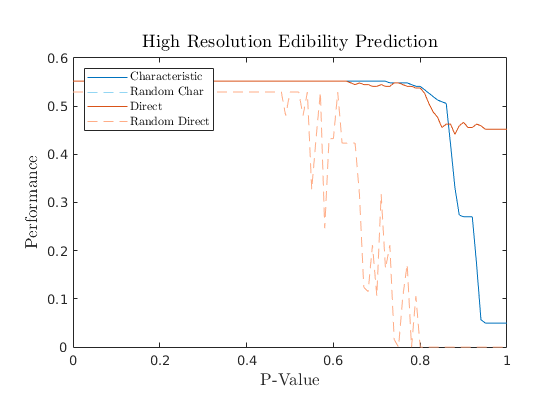

name = "High Resolution Species Prediction"

aucC =    0.079533850000000


aucD =    0.092766215000000


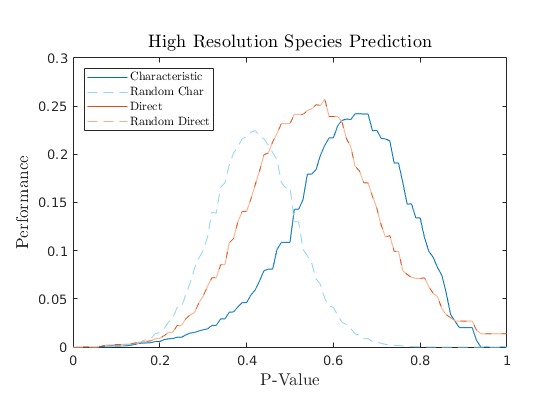

name = "Low Resolution Edibility Prediction"

aucC =    0.509750710000000


aucD =    0.510569210000000


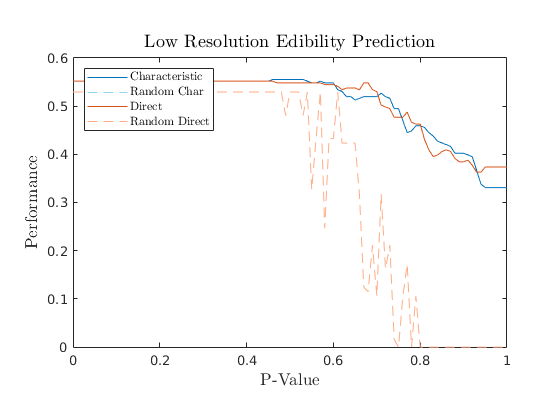

name = "Low Resolution Species Prediction"

aucC =    0.087630745000000


aucD =    0.104066905000000


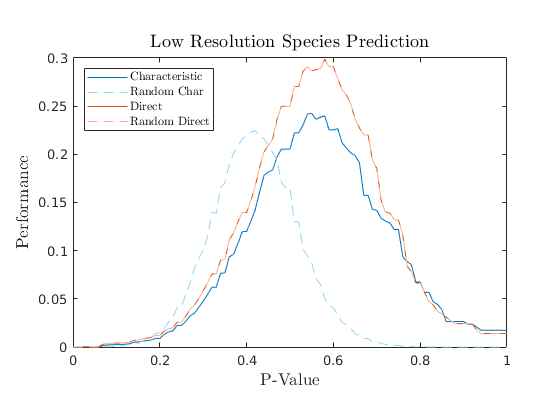

format long
files = dir("performance_data/*_perform.csv");
names = string.empty(length(files), 0);
for i = 1:length(files)
    names(i) = files(i).name;
end
names = names';
cfiles = names(contains(names, "characteristic"));
clen = length('characteristic');
dfiles = names(contains(names, "direct"));
dlen = length('direct');

PB = readmatrix("performance_data/random_char_perform.csv")';
PBE = readmatrix("performance_data/random_char_ed_perform.csv")';
PD = readmatrix("performance_data/random_direct_perform.csv")';
PDE = readmatrix("performance_data/random_direct_ed_perform.csv")';
for i= 1:length(cfiles)
    cf = cfiles(i);
    suffix = cf{1}(clen+1:end);
    name = title_from_suffix(suffix)
    df = dfiles(dfiles == "direct" + suffix);
    PC = readmatrix("performance_data/" + cf)';
    PD = readmatrix("performance_data/" + df)';
    
    figure
    
    if contains(name, "edibility", "IgnoreCase", true)
    plotP(PC, PD, PBE, PDE, name);
    else
    plotP(PC, PD, PB, PD, name);
    end
    title(name, "FontSize",14)
    saveas(gcf, "plots/" + replace(name, newline, "") + ".png")
end

% > EXPECTATIONS
PP = readmatrix("performance_data/perfect_perform.csv")';
PD = readmatrix("performance_data/random_direct_perform.csv")';
plot(PP(:,1), PP(:,2));
hold on
plot(PB(:,1), PB(:,2));
plot(PD(:,1), PD(:,2));
hold off

aucP = trapz(PP(:,1), PP(:,2))

aucP =    0.454742305000000


aucB = trapz(PB(:,1), PB(:,2))

aucB =    0.053658910000000


aucS = trapz(PD(:,1), PD(:,2))

aucS =    0.081675898103500


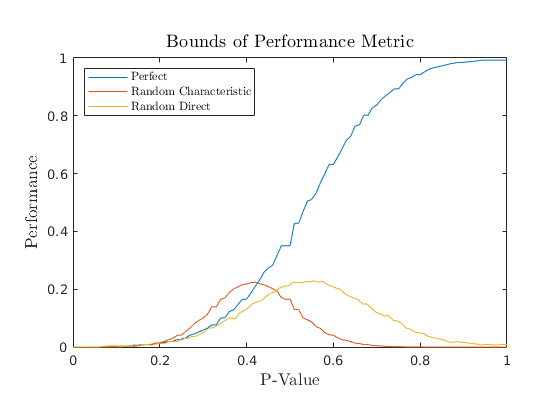


xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("Performance", "Interpreter","latex", "FontSize",13);
title("Bounds of Performance Metric", "Interpreter","latex", "FontSize",14);
legend("Perfect",...+newline+"AUC="+aucP,...
    "Random Characteristic",...+newline+"AUC="+aucB,...
    "Random Direct",...+newline+"AUC="+aucS,...
    "Location","northwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/Perfect Performance.png")


% TAU HAT EXPECTATIONS
PH = readmatrix("performance_data/bolete.h5_tau_hat_similarity.csv")';
PL = readmatrix("performance_data/bolete_lowres.h5_tau_hat_similarity.csv")';
plot(PH(:,1), PH(:,2));
hold on
plot(PL(:,1), PL(:,2));
hold off

aucH = trapz(PH(:,1), PH(:,2))

aucH =    0.516700000000000


aucL = trapz(PL(:,1), PL(:,2))

aucL =    0.484050000000000


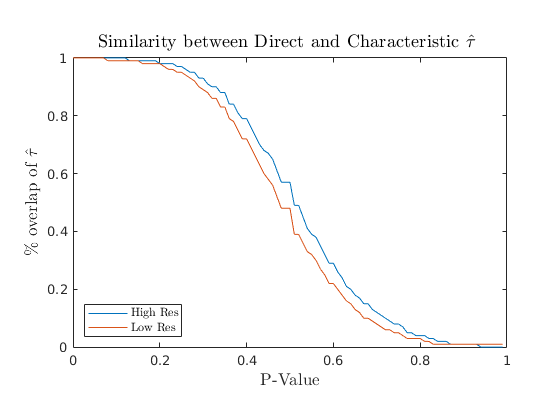


xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("\% overlap of $\hat{\tau}$", "Interpreter","latex", "FontSize",13);
title("Similarity between Direct and Characteristic $\hat{\tau}$ ", "Interpreter","latex", "FontSize",14);
l = legend("High Res",...
    "Low Res",...
    "Location","southwest", "Interpreter","latex");
pbaspect([1.5,1,1])
saveas(gcf, "plots/TauHat Similarity.png")

function plotP(PC, PD, PB, PS, name)
plot(PC(:,1), PC(:,2), "Color", '#0072BD');
hold on
plot(PB(:,1), PB(:,2), '--', "Color",1-[0.8500 0.3250 0.0980]*.5);

plot(PD(:,1), PD(:,2), "Color", '#D95319');
%     brighten(0.1)
plot(PS(:,1), PS(:,2), '--', "Color",1-[0 0.6470 0.9410]*.5);
hold off
xlabel("P-Value", "Interpreter","latex", "FontSize",13);
ylabel("Performance", "Interpreter","latex", "FontSize",13);
aucC = trapz(PC(:,1), PC(:,2))
aucD = trapz(PD(:,1), PD(:,2))
aucB = trapz(PB(:,1), PB(:,2));
aucS = trapz(PS(:,1), PS(:,2));

title(name, "Interpreter","latex");
l = legend(["Characteristic",...+newline+"AUC="+aucC, ...
    "Random Char",...+newline+"AUC="+aucB,...
    "Direct",...+newline+"AUC="+aucD,...
    "Random Direct",...+newline+"AUC="+aucS,...
    ], "Location","northwest", "Orientation","vertical", "Interpreter","latex");
%     ], "Location","southoutside", "Orientation","horizontal");
        

% l.Units = "pixels";
f = gcf;
a = gca;
a.Units = "pixels";
% f.Position(3) = 600;
% oldheight = f.Position(4);
% f.Position(4) = f.Position(4) + l.Position(4);
% a.Position(4) = oldheight - l.Position(4);
pbaspect([1.5,1,1])
% l.Position(1) = 0.1;
% f.Position(3) = f.Position(3) + l.Position(3);
end
function tit = title_from_suffix(suffix)
tit = "";
suffix = string(suffix);
if contains(suffix, "_bolete.h5")
    tit = tit + "High Resolution";
else
    tit = tit + "Low Resolution";
end
if contains(suffix, "_ed")
    tit = tit + " Edibility Prediction";
else
    tit = tit + " Species Prediction";
end
end